Параметры системы

A = [0 1;
     9 0];
B_1 = [1;
       3];
B_2 = [1;
       0];
D_1 = [-5];
C_1 = [2 -3];

C_2 = [1 0;
    0 1;
    0 0];
D_2 = [0; 0; 1];

x_0 = [3; 8];
gamma1 = 10.37;
gamma2 = 15;
gamma3 = 100;

**Первая система**

Матрица регулятора и наблюдателя

[Q_1, K_1, P_1, L_1] = Hinf_controller_observer(A, B_1, B_2, C_1, C_2, D_1, D_2, gamma1)

Hinf_controller_observer is not found in the current folder or on the MATLAB path, but exists in:
    /Users/evdokiiagalkina/Downloads/Lab11

Change the MATLAB current folder or add its folder to the MATLAB path.

Передаточная функция и вычисление норм

sys_1 = ss([A, B_2*K_1; -L_1*C_1, A+B_1*gamma1^(-2)*B_1'*Q_1+B_2*K_1+L_1*(C_1+D_1*gamma1^(-2)*B_1'*Q_1)],[B_1; -L_1*D_1], [C_2, D_2*K_1],0);
[num1, den1] = sys2TfParam(sys_1);
disp(num1)
disp(den1)

G1 = [tf(num1(1), den1(1));
    tf(num1(2), den1(2));
    tf(num1(3), den1(3))];
disp(norm(G1, 2))
disp(hinfnorm(G1))

**Вторая система**

Матрица регулятора и наблюдателя

[Q_2, K_2, P_2, L_2] = Hinf_controller_observer(A, B_1, B_2, C_1, C_2, D_1, D_2, gamma2)

Q_2 =     6.8002    2.4637
    2.4637    1.0663


K_2 =    -6.8002   -2.4637


P_2 =     3.2909    9.8726
    9.8726   29.6179


L_2 =     1.8616
    5.5848


Передаточная функция и вычисление норм

sys_2 = ss([A, B_2*K_2; -L_2*C_1, A+B_1*gamma2^(-2)*B_1'*Q_2+B_2*K_2+L_2*(C_1+D_1*gamma2^(-2)*B_1'*Q_2)],[B_1; -L_2*D_1], [C_2, D_2*K_2],0);
[num2, den2] = sys2TfParam(sys_2);
disp(num2)

    {[  0 1.0000 -108.1101 -373.5329 -120.6076]}
    {[  0 3.0000 71.9477 -565.8093 -2.2640e+03]}
    {[0 -132.0927 -581.2079 79.2556 1.9021e+03]}



disp(den2)

    {[1 20.9826 135.7273 365.9461 361.8227]}
    {[1 20.9826 135.7273 365.9461 361.8227]}
    {[1 20.9826 135.7273 365.9461 361.8227]}




G2 = [tf(num2(1), den2(1));
    tf(num2(2), den2(2));
    tf(num2(3), den2(3))];
disp(norm(G2, 2))

   25.7873



disp(hinfnorm(G2))

    9.6423



**Третья система**

Матрица регулятора и наблюдателя

[Q_3, K_3, P_3, L_3] = Hinf_controller_observer(A, B_1, B_2, C_1, C_2, D_1, D_2, gamma3)

Q_3 =     6.6704    2.4153
    2.4153    1.0481


K_3 =    -6.6704   -2.4153


P_3 =     3.2213    9.6638
    9.6638   28.9913


L_3 =     0.9129
    2.7388


Передаточная функция и вычисление норм

sys_3 = ss([A, B_2*K_3; -L_3*C_1, A+B_1*gamma3^(-2)*B_1'*Q_3+B_2*K_3+L_3*(C_1+D_1*gamma3^(-2)*B_1'*Q_3)],[B_1; -L_3*D_1], [C_2, D_2*K_3],0);
[num3, den3] = sys2TfParam(sys_3);
disp(num3)

    {[  0 1.0000 -47.4508 -165.7116 -43.0773]}
    {[0 3.0000 48.2154 -230.3397 -1.0440e+03]}
    {[ 0 -63.5226 -279.4995 38.1136 914.7258]}



disp(den3)

    {[1 13.0718 65.5726 149.1489 129.2318]}
    {[1 13.0718 65.5726 149.1489 129.2318]}
    {[1 13.0718 65.5726 149.1489 129.2318]}




G3 = [tf(num3(1), den3(1));
    tf(num3(2), den3(2));
    tf(num3(3), den3(3))];
disp(norm(G3, 2))

   19.8212



disp(hinfnorm(G3))

   11.1571



**Построение графиков**

График сингулярных чисел

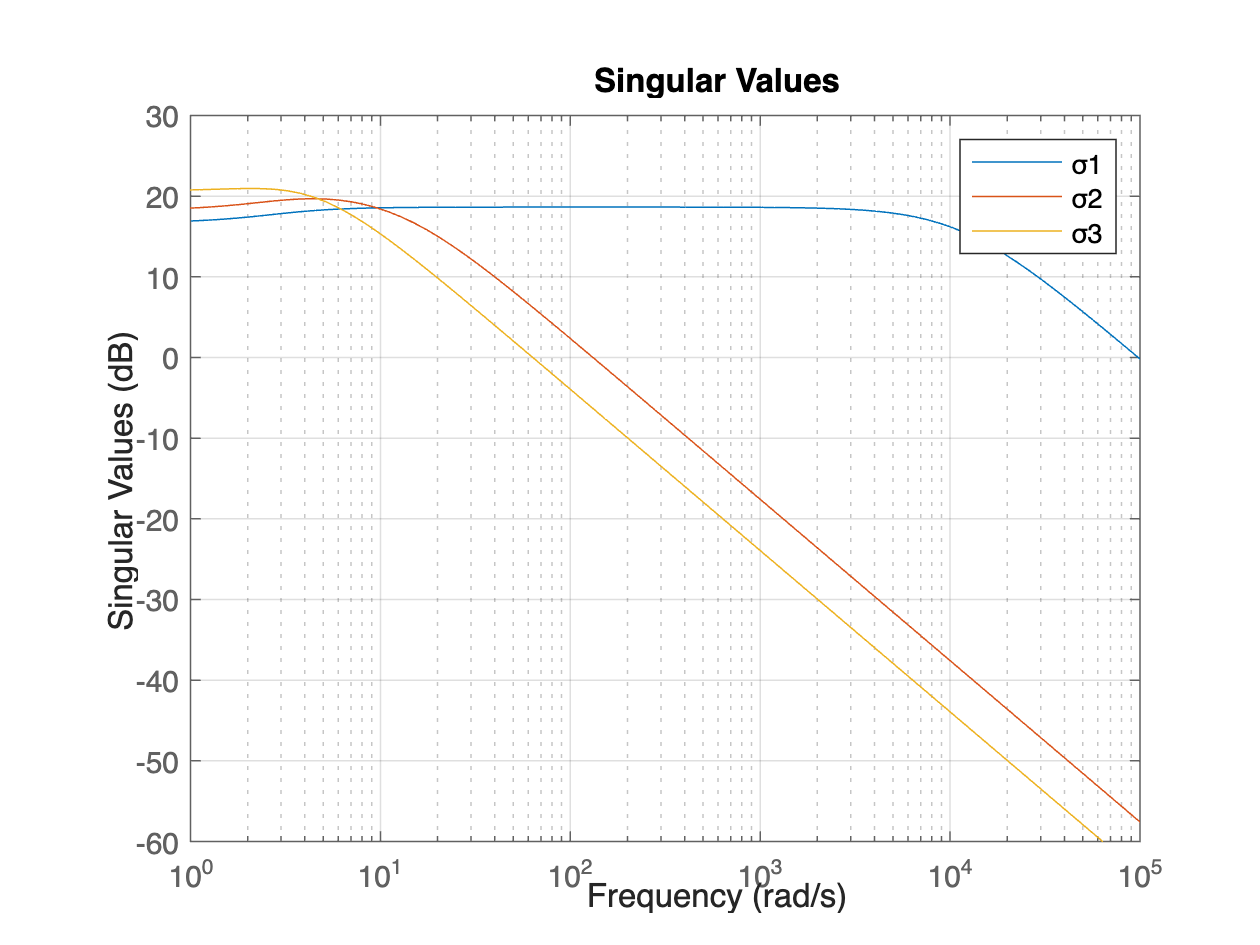

sigma(sys_1);
hold on;
grid on;
sigma(sys_2);
hold on;
sigma(sys_3);
legend('σ1', 'σ2', 'σ3');
hold off;

Покомпонентные АЧХ системы

bodemag(sys_1);
hold on;
grid on;
bodemag(sys_2);
hold on;
bodemag(sys_3);
legend('System 1', 'System 2', 'System 3');
hold off;

Построение графиков с возмущающим воздействием

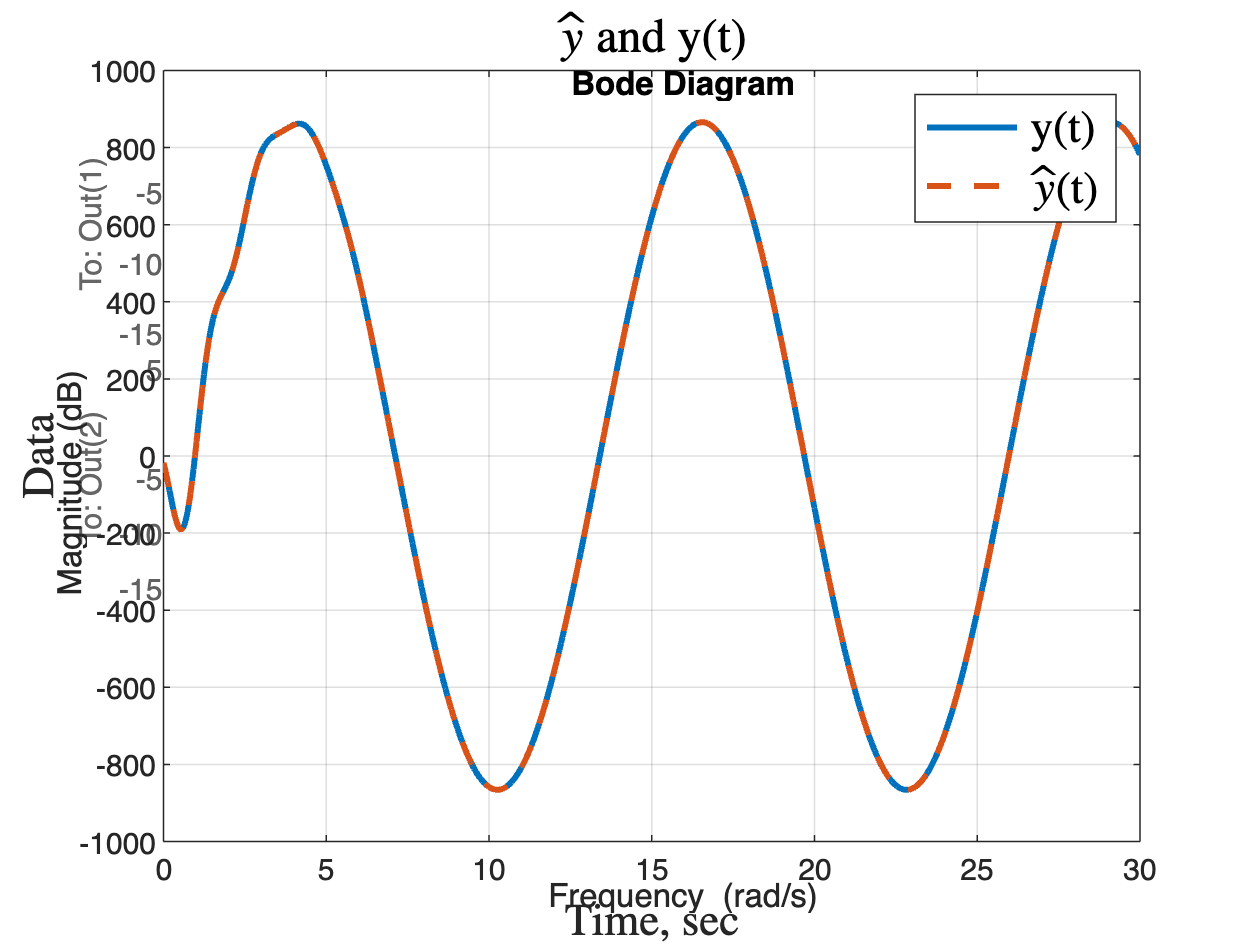

x_0 = [3; 8];


% plot(out.z.Time, out.z.Data(:, 1), LineWidth=2.0);
% hold on;
% plot(out.z1.Time, out.z1.Data(:, 1), LineWidth=2.0);
% title('$z_{1}(t)$','Interpreter', 'latex', 'FontSize', 16);
% xlabel('time', 'Interpreter', 'latex', 'FontSize', 15);
% ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
% legend('System 1', 'System 2', 'Interpreter', 'latex', 'FontSize', 15);
% grid on;
% 
% hold off;
% plot(out.z.Time, out.z.Data(:, 2), LineWidth=2.0);
% hold on;
% plot(out.z1.Time, out.z1.Data(:, 2), LineWidth=2.0);
% title('$z_{2}(t)$','Interpreter', 'latex', 'FontSize', 16);
% xlabel('time', 'Interpreter', 'latex', 'FontSize', 15);
% ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
% legend('System 1', 'System 2', 'Interpreter', 'latex', 'FontSize', 15);
% grid on;
% 
% hold off;
% plot(out.z.Time, out.z.Data(:, 3), LineWidth=2.0);
% hold on;
% plot(out.z1.Time, z1(:, 3), LineWidth=2.0);
% grid on;
% title('$z_{u}(t)$','Interpreter', 'latex', 'FontSize', 16);
% xlabel('time', 'Interpreter', 'latex', 'FontSize', 15);
% ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
% legend('System 1', 'System 2', 'Interpreter', 'latex', 'FontSize', 15);

z = reshape(out.z.Data,[3,200042])';
z1 = reshape(out.z1.Data,[3,200042])';
hold off;

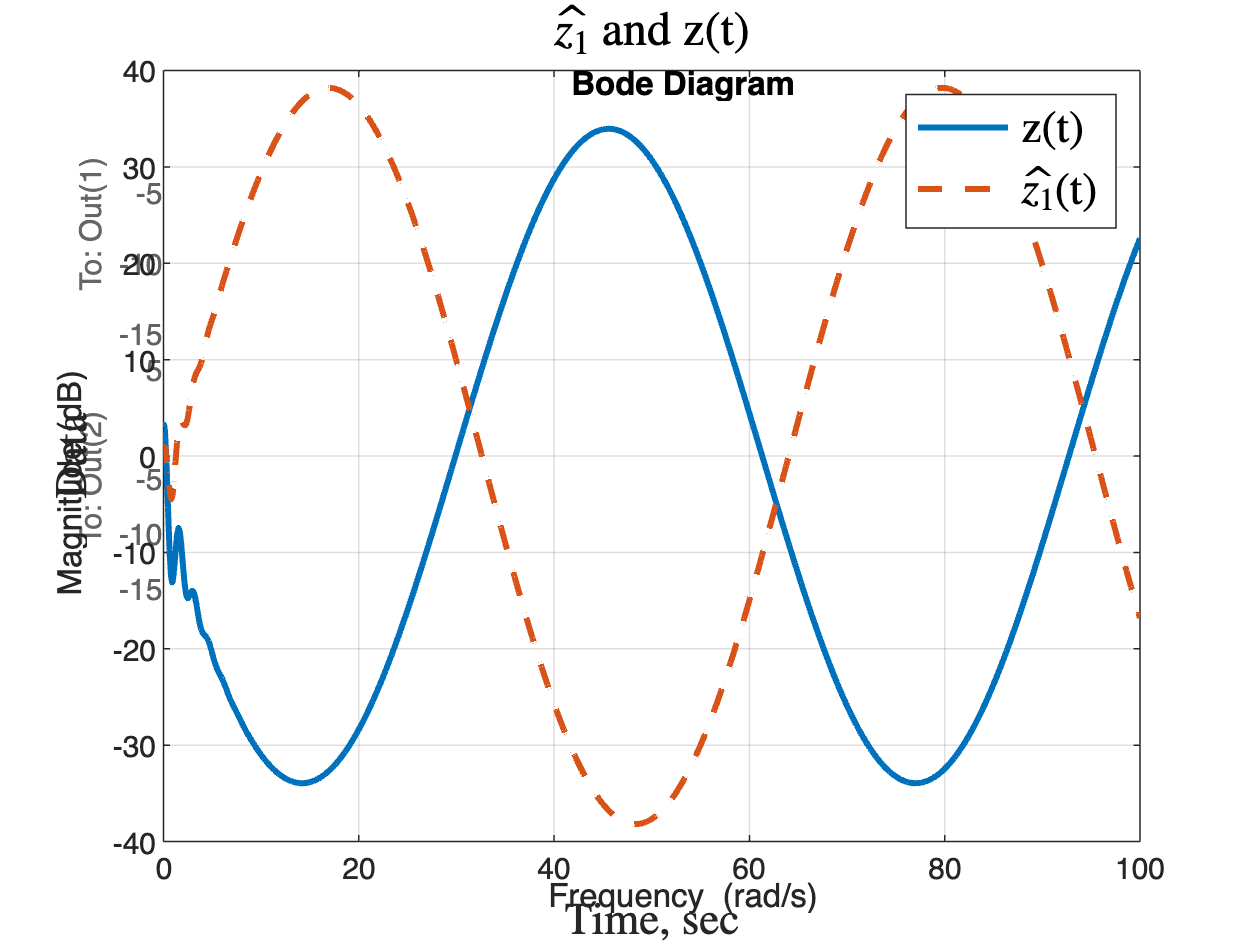

plot(out.z.Time, z(:, 1), LineWidth=2.0);
hold on;
plot(out.z1.Time, z1(:, 1), LineWidth=2.0, LineStyle="--");
grid on;
title('$\hat{z_{1}}$ and z(t)','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("z(t)","$\hat{z_{1}}$(t)", 'Interpreter', 'latex', 'FontSize', 15);

hold off;

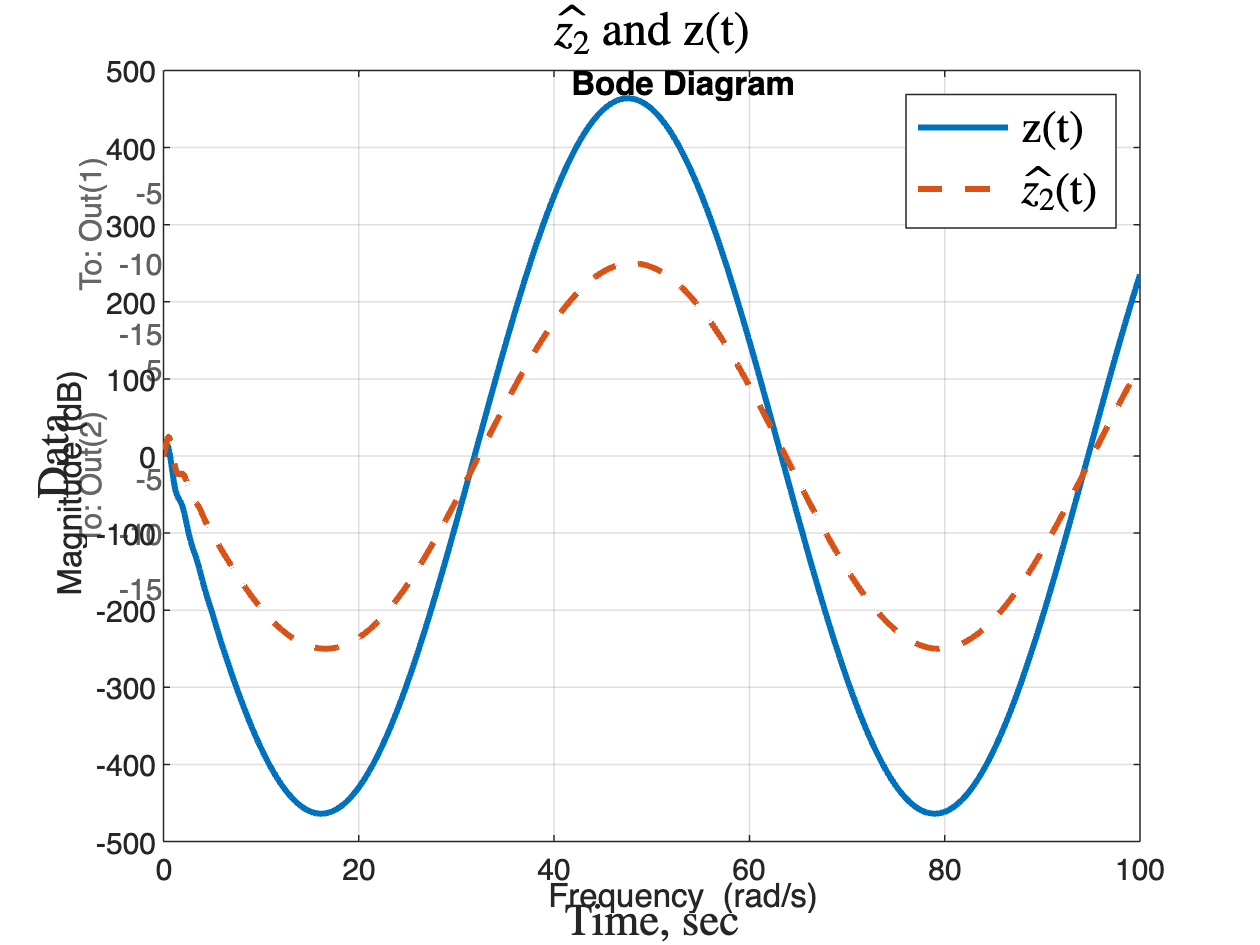

plot(out.z.Time, z(:, 2), LineWidth=2.0);
hold on;
plot(out.z1.Time, z1(:, 2), LineWidth=2.0, LineStyle="--");
grid on;
title('$\hat{z_{2}}$ and z(t)','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("z(t)","$\hat{z_{2}}$(t)", 'Interpreter', 'latex', 'FontSize', 15);

hold off;

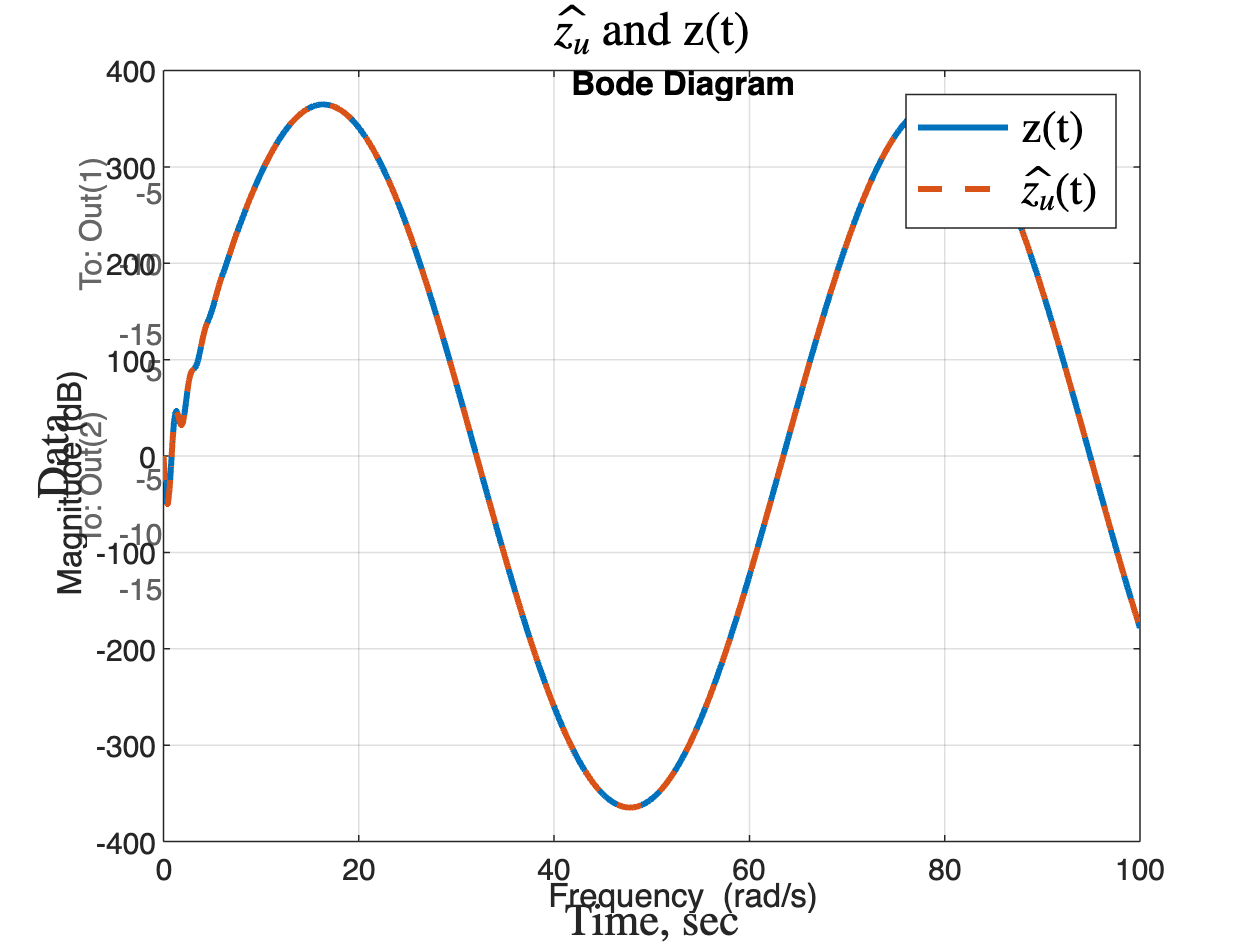

plot(out.z.Time, z(:, 3), LineWidth=2.0);
hold on;
plot(out.z1.Time, z1(:, 3), LineWidth=2.0, LineStyle="--");
grid on;
title('$\hat{z_{u}}$ and z(t)','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("z(t)","$\hat{z_{u}}$(t)", 'Interpreter', 'latex', 'FontSize', 15);

hold off;

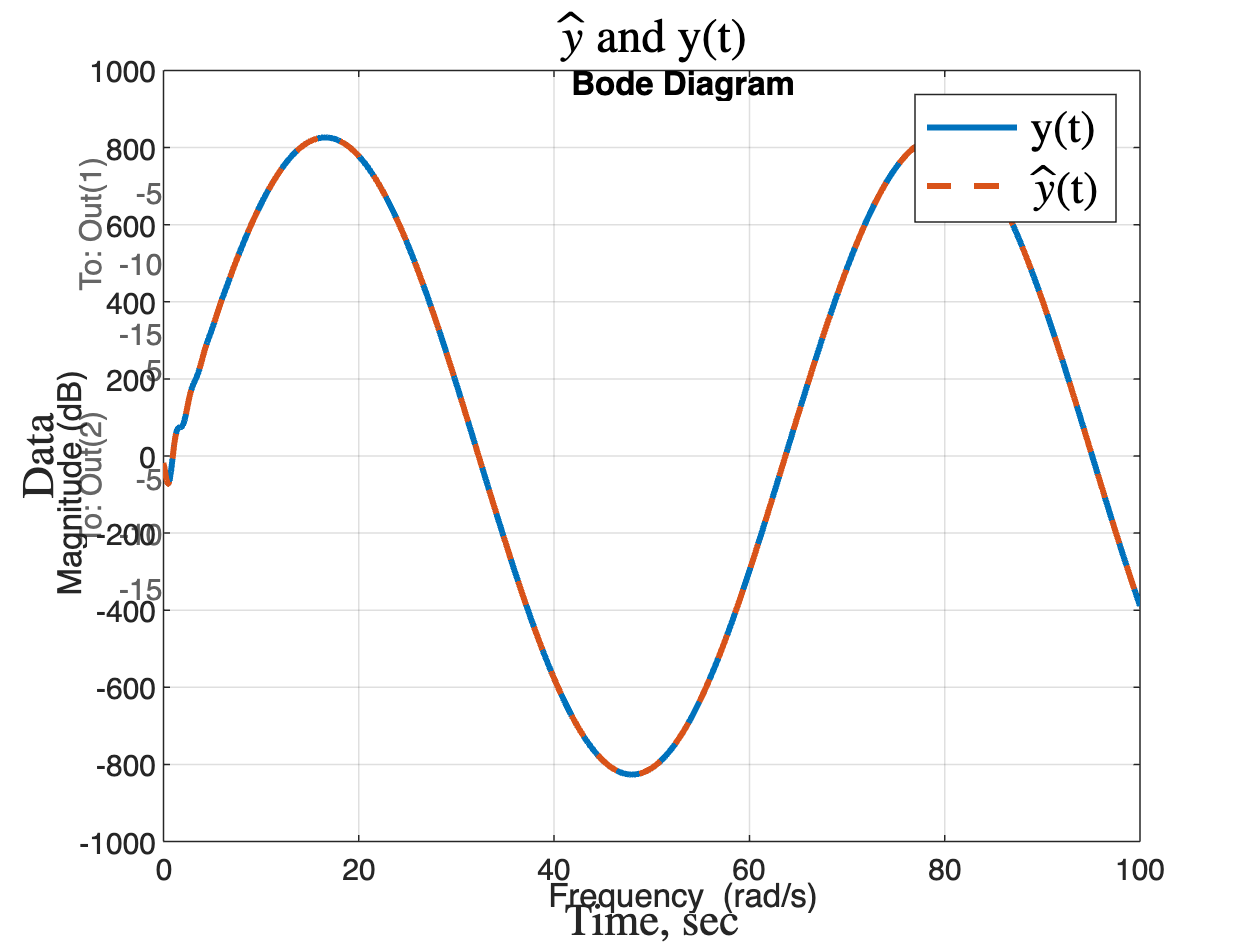

plot(out.y1.Time, out.y1.Data(:, 1), LineWidth=2.0);
hold on;
plot(out.y.Time, out.y.Data(:, 1), LineWidth=2.0, LineStyle="--");
grid on;
title('$\hat{y}$ and y(t)','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("y(t)","$\hat{y}$(t)", 'Interpreter', 'latex', 'FontSize', 15);